# A AE 567 HW4 Problem 3

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
outdir = pwd + "\output\hw4";
mdir = pwd + "\mfiles\hw4";

m = 2;
% Define expectations 
syms x v y g
y = x + v;
g = [];
for n = 0:m
    g = [g; y^n];
end
xl = 0; xu = 10;  % range of x
vl = 0; vu = 4;  % range of v
fx = 1 / (xu - xl); 
fv = 1 / (vu - vl); 

EX = @(A) int(fx * x.^A, xl, xu);
EV = @(A) int(fv * v.^A, vl, vu);
EY = @(A) fx * fv * int(int(y.^A, x, xl, xu), vl, vu);
EXY = @(A,B) fx * fv * int(int(x.^A * y.^B, x, xl, xu), vl, vu);

% P_Hx
Rfg = EXY(1, 0:m);
A = [];
for n = 0:m
    A = [A; n:n+m];
end
Rg = EY(A);
coef = Rfg * inv(Rg);
coef = eval(coef);
% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg';
d4 = sqrt(d4sq);

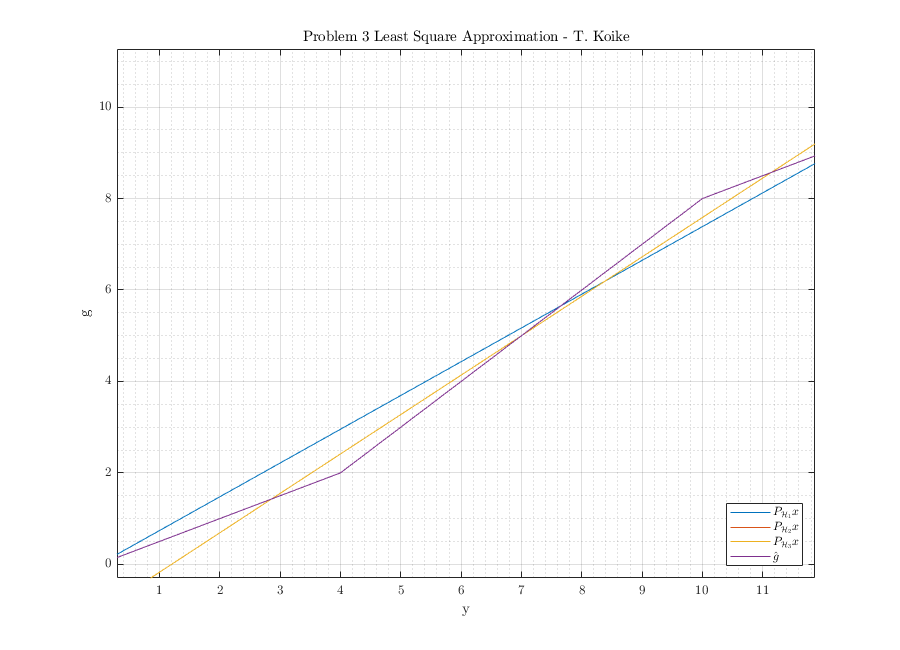

% Plotting
t = 0:0.01:14;

% ghat piecewise
t1 = t(0 <= t & t < 4);
t2 = t(4 <= t & t < 10);
t3 = t(10 <= t & t <= 14);
ghat = [t1 ./ 2, t2 - 2, (t3 + 6)/2];

% PHx
Ph3x = 0;
for n = 1:length(coef)
    Ph3x = Ph3x + coef(n)*t.^(n-1);
end

Ph1x = 130 * t / 176;
Ph2x = -30/29 + 25/29*t;

fig = figure("Renderer","painters",'Position',[60 60 900 650]);
    plot(t, Ph1x)
    grid on; grid minor; box on; hold on;
    plot(t, Ph2x)
    plot(t, Ph3x)
    plot(t, ghat)
    hold off;
    title('Problem 3 Least Square Approximation - T. Koike')
    legend('$P_{\mathcal{H}_1}x$','$P_{\mathcal{H}_2}x$',...
       '$P_{\mathcal{H}_3}x$', '$\hat{g}$', "Location","best")
    xlabel('y')
    ylabel('g')
saveas(fig, fullfile(outdir, 'p3_lsqr_plot.png'));

% Save file as .m
matlab.internal.liveeditor.openAndConvert('hw4_p3.mlx', ...
    convertStringsToChars(fullfile(mdir, 'hw4_p3.m')));

$$ans = \left(\begin{array}{ccc} 1 & 7 & 58.6667\\ 7 & 58.6667 & 546\\ 58.6667 & 546 & 5.4379e+03 \end{array}\right)$$